## Setting Up

clear all
close all
clc
currentFolder = 'C:\Users\danielhochbaum\Dropbox (HMS)\Hyperthyroid\hyperData';
saveFolder = 'C:\Users\danielhochbaum\Dropbox (HMS)\Hyperthyroid\hyperData';
cd(currentFolder);
load CompiledPhysio_final.mat

## Reconfiguring Tables

0. masterID reconfiguring

masterIDII = removevars(masterID,{'Spreadsheet' 'ImportantNotes' 'Var14' 'Var15' 'Var16' 'Var17' 'Var18' 'Var19' 'Var20'});

1.Temp reconfiguring

ID=tempMasterData.Properties.RowNames;
IDa = cell2table(ID);
IDa.Properties.RowNames = ID;
tempmasterII=[IDa tempMasterData];
tempmasterII = removevars(tempmasterII, {'OriginalID'});
tempmasterII.Properties.VariableNames = {'Master_ID','-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};
dataprestack=join(tempmasterII,masterIDII);

2.Weight

weightmasterII=[IDa weightMasterData];
weightmasterII = removevars(weightmasterII, {'OriginalID'});
weightmasterII.Properties.VariableNames = {'Master_ID' '-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};

3.Food

foodmasterII=[IDa deltaFoodData];
foodmasterII.Properties.VariableNames = {'Master_ID' '-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'};

## Stacking Individual Tables

prelimstack=stack(dataprestack,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});
weightstack=stack(weightmasterII,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});
foodstack=stack(foodmasterII,{'-3' '-2' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});

## Renaming Columns to Join Stacks

prelimstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Temp';
prelimstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator'}='Day';
weightstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Weight';
foodstack.Properties.VariableNames{'-3_-2_-1_0_1_2_3_4_5_6_7_8'}='Food';

## Reconfiguring Stacks to Join

weightstack.("-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator")=[];
foodstack.("-3_-2_-1_0_1_2_3_4_5_6_7_8_Indicator")=[];
weightstack.Master_ID=[];
foodstack.Master_ID=[];

## Joining Stacks

alldata = [prelimstack,foodstack,weightstack];

## Find indices of baseline days

%pull out baseline days
daysAsInt = str2double((categories(alldata.Day)));
tmp = double(alldata.Day); %get indices of each categorical
allDays = daysAsInt(tmp); %vector of days as integers
baselineInd = allDays < 1; %find habituation days and treatment day 0;

## Find outliers by examining baseline food consumption

look for animals that have abberrant days of food consumption during baseline. Set those days to NaN as likely measurement errors.

First find the distribution of baseline food consumption.

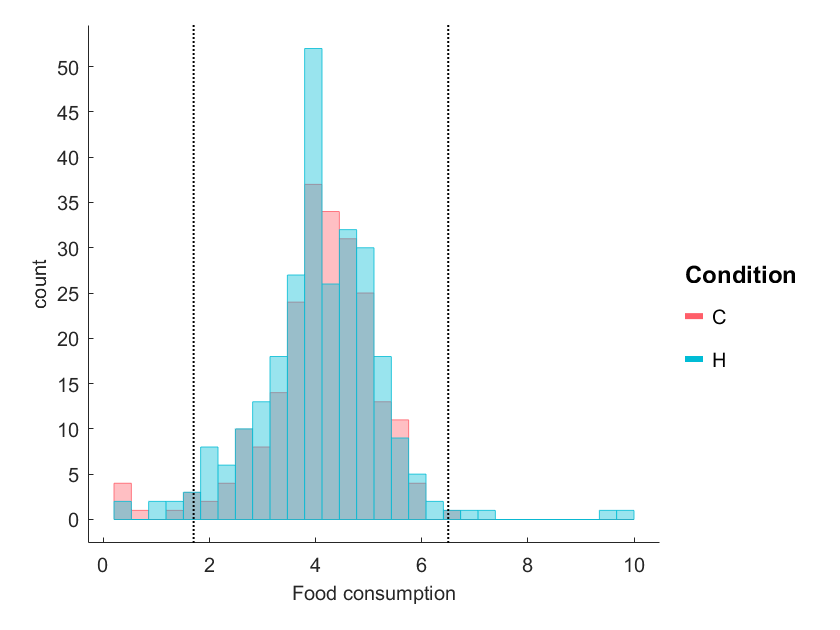

baselineFood = alldata.Food(baselineInd);
% stdFood = nanstd(baselineFood);
madFood = mad(baselineFood,1);
% avgBaselineFood = nanmean(baselineFood);
medBaselineFood = nanmedian(baselineFood);

g = gramm('x',alldata.Food(baselineInd),'color',alldata.Condition_H_C_(baselineInd));
g.stat_bin('geom','overlaid_bar');
%show 4 median absolute deviations away from median Food consumption
g.geom_vline('xintercept',[medBaselineFood-4*madFood,medBaselineFood+4*madFood], 'style','k:') ;
g.set_names('x','Food consumption','color','Condition');
g.draw();

%find names of outliers 4 median absolute deviations away from median Food consumption
foodOutliers = baselineFood > medBaselineFood+4*madFood | baselineFood < medBaselineFood-4*madFood;
tmpIDs = alldata.Master_ID(baselineInd);
tmpIDs = tmpIDs(foodOutliers);
disp(tmpIDs)

    'H13'
    'H14'
    'H71'
    'H71'
    'H80'
    'H89'
    'H89'
    'H90'
    'H96'
    'H112'
    'H114'
    'H145'
    'H148'
    'H158'
    'H184'
    'H200'
    'H214'
    'H215'
    'H223'



percKickedOut = 100*length(tmpIDs)/length(baselineInd);
disp(['removed ' num2str(percKickedOut) '% of baseline food intake data'])

removed 0.60664% of baseline food intake data


%replace outlier food intake with NaN
alldataII = alldata;
outlierFoodRemoved = baselineFood;
outlierFoodRemoved(foodOutliers) = NaN;
alldataII.Food(baselineInd) = outlierFoodRemoved;

## Calculate baseline temp, weight, deltaFood, for each animal

%extract temp baseline
[alldataIII, noBaseline] = addBaseline(alldataII,baselineInd,'Temp');

animals with no baseline exist


sum(noBaseline) %one animal has no baseline measurement

ans = 1

noBaselineII = noBaseline;

%extract weight baseline
[alldataIII, noBaseline] = addBaseline(alldataIII,baselineInd,'Weight');

sum(noBaseline) %all animals have baseline

ans = 0

noBaselineII = noBaseline + noBaselineII;

%extract deltaFood baseline
[alldataIII, noBaseline] = addBaseline(alldataIII,baselineInd,'Food');

animals with no baseline exist


sum(noBaseline) %10 animals have no baseline measurement

ans = 16

noBaselineII = noBaseline + noBaselineII;

## Find animals with no baseline

noBaselineAnimals = IDa(noBaselineII > 0,"ID")

noBaselineAnimals = 16×1 table
               ID   
            ________

    H8      {'H8'  }
    H27     {'H27' }
    H28     {'H28' }
    H43     {'H43' }
    H44     {'H44' }
    H45     {'H45' }
    H46     {'H46' }
    H47     {'H47' }
    H48     {'H48' }
    H49     {'H49' }
    H89     {'H89' }
    H96     {'H96' }
    H184    {'H184'}
    H214    {'H214'}
    H215    {'H215'}
    H223    {'H223'}


animals with no baseline measurements in one or more categories:

H8, H27, H28, H43, H44, H45, H46, H47, H48, H49

Lost all baseline food measurements due to outlier status: H89, H96, H184, H214, H215, H223 (6/261 = 2.3% of animals), or excluding 10 animals without baseline measures: 6/251 = 2.4% of animals).

look at data for verification, eg:

alldataIII(cellfun(@(x) strcmp(x,'H223'), alldataIII.Master_ID),:)

ans = 12×18 table
               Master_ID    Original_ID    Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_          OriginalExp          Round    Day    Temp    Food    Weight    baselineTemp    baselineWeight    baselineFood
               _________    ___________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _______________________    ___

## Exclude animals without baseline measurements

This will ensure that we are looking at the same set of animals across graphs

alldataIV = alldataIII(~ismember(alldataIII.Master_ID, noBaselineAnimals.ID),:);

## Calculate deltaTemp, deltaWeight, deltaDeltaFood

and add to 'alldataIV':

alldataIV.deltaTemp = alldataIV.Temp-alldataIV.baselineTemp;
alldataIV.deltaWeight = alldataIV.Weight-alldataIV.baselineWeight;
alldataIV.deltaFood = alldataIV.Food-alldataIV.baselineFood;

## Calculate normTemp, normWeight, normDeltaFood

and add to 'alldataIV':

alldataIV.normTemp = alldataIV.Temp./alldataIV.baselineTemp;
alldataIV.normWeight = alldataIV.Weight./alldataIV.baselineWeight;
alldataIV.normFood = alldataIV.Food./alldataIV.baselineFood;

## Calculate percTemp, percWeight, percDeltaFood

and add to 'alldataIV':

alldataIV.percTemp = (alldataIV.normTemp-1)*100;
alldataIV.percWeight = (alldataIV.normWeight-1)*100;
alldataIV.percFood = (alldataIV.normFood-1)*100;

## Finally, find animals that lack genotype, sex, condition, or age data, and remove from stack

%genotype
geno = alldataIV.Genotype;
tmpGeno = unique(geno);
disp(tmpGeno);

    'Robo3+/+'
    'WT'



%sanity check:
indGeno1 = strcmp(geno,tmpGeno(1));
indGeno2 = strcmp(geno,tmpGeno(2));
indGeno = indGeno1+indGeno2;
sum(indGeno)/length(geno)

ans = 1

looks like all genotypes are either Robo3+/+, WT, no missing values

%sex
sex = alldataIV.Sex_M_F_;
tmpSex = unique(sex);
disp(tmpSex);

    'F'
    'M'



%sanity check:
indSex1 = strcmp(sex,tmpSex(1));
indSex2 = strcmp(sex,tmpSex(2));
indSex = indSex1+indSex2;
sum(indSex)/length(sex)

ans = 1

looks like all sex are either F/M, no missing values

%condition
cond = alldataIV.Condition_H_C_;
tmpCond = unique(cond);
disp(tmpCond);

    'C'
    'H'



%sanity check:
indCond1 = strcmp(cond,tmpCond(1));
indCond2 = strcmp(cond,tmpCond(2));
indCond = indCond1+indCond2;
sum(indCond)/length(cond)

ans = 1

looks like conditions are either C/H, no missing values

%age
age = alldataIV.AgeAtExp_InjectionStart_days_;
indNoAge = isnan(age);
disp(unique(alldataIV.Master_ID(indNoAge)))

    'H11'
    'H12'
    'H13'
    'H136'
    'H137'
    'H14'
    'H207'
    'H208'
    'H209'
    'H210'



10 animals have no age listed. Remove from stack

%remove animals with no listed age from stack
alldataV = alldataIV;
alldataV(indNoAge,:) = [];

%final number of animals
disp(length(unique(alldataV.Master_ID)))

   235



## Save master stacked table for figure generation

cd(saveFolder)
save('masterStackTable', "alldataV")

## %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Local Functions

### function to extract baseline measurements:

function [alldataII, noBaseline] = addBaseline(alldata, baselineInd, baselineColumnHeader)
    baseline = alldata(baselineInd,{'Master_ID','Day',baselineColumnHeader}); %create a baseline table
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % NOTE - MUST RETAIN 'Master_ID' so that join() function knows how to %
    % map values back onto alldata table.                                 %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    baseline = unstack(baseline, baselineColumnHeader,'Day'); %make each Day into a column
    ID=baseline.Master_ID;
    baseline = table2array(baseline(:,2:end)); %turn into an array [animals x days]
    baseline = nanmean(baseline,2); %get mean baseline per animal
    noBaseline = isnan(baseline); %find animals with no baseline measurements
    if sum(noBaseline) > 0
        disp('animals with no baseline exist')
    end
    baseline = array2table(baseline); %turn back into table
    baseline = [ID, baseline]; %add ID to map back onto alldata
    baseline.Properties.VariableNames = {'Master_ID', ['baseline' baselineColumnHeader]}; %change variable names to match to alldata;

    alldataII = join(alldata,baseline);
    
end